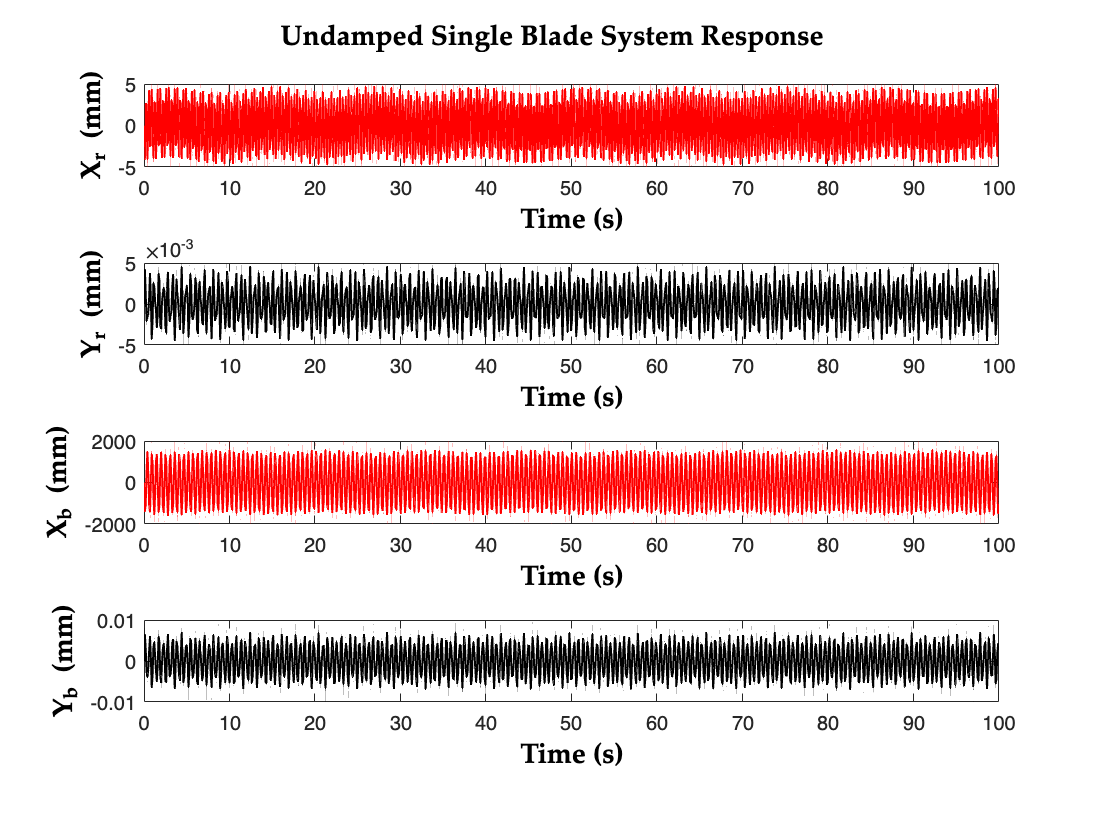

%%ASEN 5022 Dynamics of Aerospace Structures Project
%%Author: Chandan Varma Tamada
%%Dynamics of Coupled Blade System
clc; clear;

%%Blade Params
m_b = 6; %Mass of Blade (kg)
len = 1.5; %Length of Blade (m)
k_b = 300*(10^5); %Spring Constant of Blade (N/m)
n = 1; %Number of Blades

%%Rotor Params
m_r = 1000; %Mass of Rotor (kg)
k_r = 300*(10^6); %Spring Constant of Rotor (N/m)
c_r = 2000;

%%External Forces Params
omega = 262.85; %Rotational Speed (rad/s)

%%Force Params
F_l = 700; %Aero Force (N)
F_c = m_b*len*(omega^2); %Centripetal Force (N)

%%Time Params
t_end = 100; %Duration of Response
del_t = 0.1; %Time Interval
t = linspace(0,t_end,t_end/del_t); %Time Matrix

%%Blade Designation Params
i = 1:n;
theta = (2*(i-1)*pi)/n;

%%Coupled Rotor Blade Matrices
M = [m_r*eye(2),zeros(2,2*n);zeros(2*n,2),m_b*eye(2*n)];
K = [(n*k_b+k_r)*eye(2) [-k_b*ones(1,n) zeros(1,n);zeros(1,n) -k_b*ones(1,n)];[-k_b*ones(n,1) zeros(n,1);zeros(n,1) -k_b*ones(n,1)] k_b*eye(2*n)];
C = [zeros(2),zeros(2,2*n);zeros(2*n,2),zeros(2*n)];
C_damped = [c_r*eye(2),zeros(2,2*n);zeros(2*n,2),zeros(2*n)];
%C_damped = [(n*(c_b/(len^2))+c_r)*eye(2) [-(c_b/(len^2))*ones(1,n) zeros(1,n);zeros(1,n) -(c_b/(len^2))*ones(1,n)];-(c_b/(len^2))*ones(2*n,2) (c_b/(len^2))*[eye(n) eye(n);eye(n) eye(n)]];
F = [k_b*len*sum(cos(theta));k_b*len*sum(sin(theta));transpose((F_c-k_b*len)*cos(theta)-F_l*sin(theta));transpose(F_l*cos(theta)+(F_c-k_b*len)*sin(theta))];

%%Space Formulation
A = [K zeros(2*n+2);zeros(2*n+2) -M];
B = [C M;M zeros(2*n+2)];
B_damped = [C_damped M;M zeros(2*n+2)];
S = [F;zeros(2*n+2,1)];

%%Eigen Problem Formulation
[V,E] = eig(A,B);
[V_damped,E_damped] = eig(A,B_damped);

%%Pre-Allocation of Solution
r = zeros(length(t),2*(2*n+2));
r_damped = zeros(length(t),2*(2*n+2));

%%For Loop to Sum over all DoFs
for j = 1:2*(2*n+2)
    r = r+state_space(V(:,j),2*n+2,A,B,S,omega,t);
    r_damped = r_damped+state_space(V_damped(:,j),2*n+2,A,B_damped,S,omega,t);
end

%%Plot
figure;
sgtitle('Undamped Single Blade System Response','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,1);
plot(t,r(:,1)*(10^3),'r','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('X_r (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,2);
plot(t,r(:,2)*(10^3),'k','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Y_r (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,3);
plot(t,r(:,3)*(10^3),'r','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('X_b (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,4);
plot(t,r(:,4)*(10^3),'k','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Y_b (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');

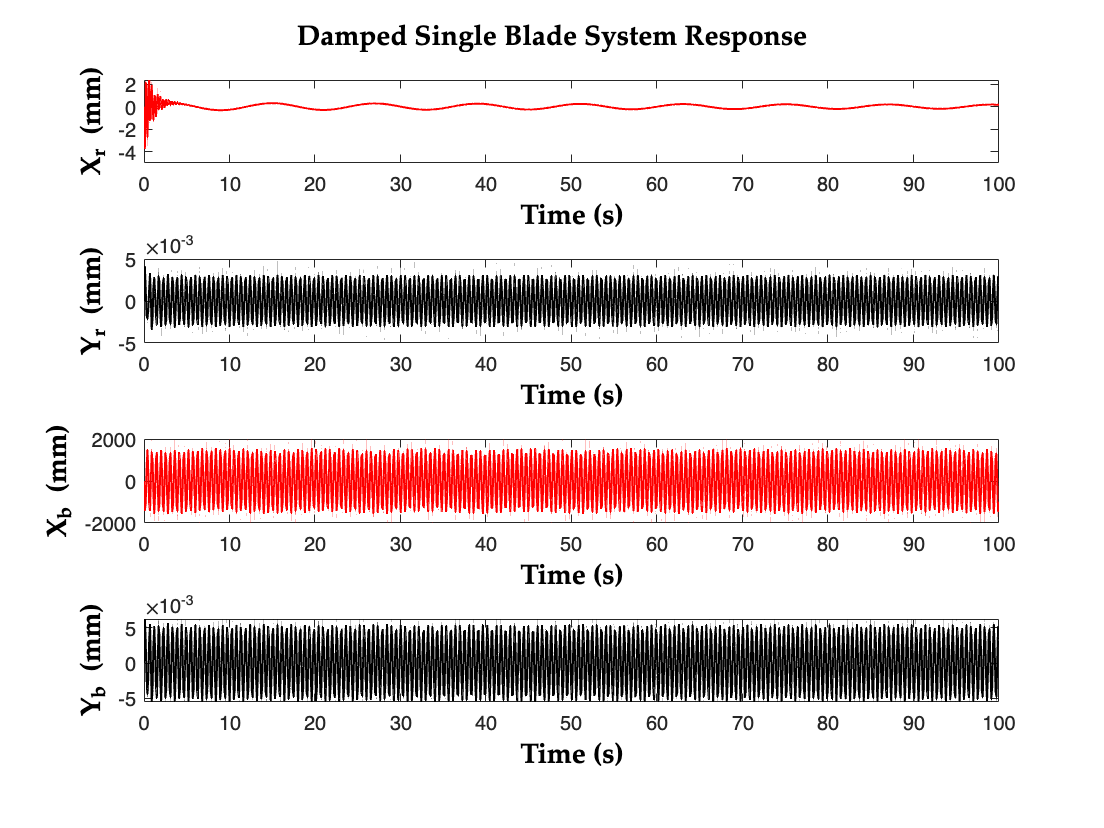

figure;
sgtitle('Damped Single Blade System Response','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,1);
plot(t,r_damped(:,1)*(10^3),'r','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('X_r (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,2);
plot(t,r_damped(:,2)*(10^3),'k','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Y_r (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,3);
plot(t,r_damped(:,3)*(10^3),'r','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('X_b (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
subplot(4,1,4);
plot(t,r_damped(:,4)*(10^3),'k','LineWidth',1);
xlabel('Time (s)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');
ylabel('Y_b (mm)','FontSize',14,'FontWeight','bold','Color','k','FontName','Palatino');


%{
%%Create Video
videoFileName = 'single_blade_undamped.mp4';
writerObj = VideoWriter(videoFileName,'MPEG-4');
writerObj.FrameRate = 50;
open(writerObj);

%%Plotting and recording frames
figure;
for k = 1:length(t)
    scatter(r(k,1),r(k,2),1500,'bo','filled');
    hold on;
    for q = 1:n
        scatter(r(k,2+q)+len*cos(theta(q)),r(k,2+n+q)+len*sin(theta(q)),400,'ro','filled');
        hold on;
        plot([r(k,1),r(k,2+q)+len*cos(theta(q))],[r(k,2),r(k,2+n+q)+len*sin(theta(q))],'k-','LineWidth',2);
    end
    axis equal;
    xlim([-3 3]);
    ylim([-3 3]);
    grid on;
    hold off;
    frame = getframe(gcf);
    writeVideo(writerObj,frame);
end

%%Close video file
close(writerObj);

%%Create Video
videoFileName = 'single_blade_damped.mp4';
writerObj = VideoWriter(videoFileName,'MPEG-4');
writerObj.FrameRate = 50;
open(writerObj);

%%Plotting and recording frames
figure;
for k = 1:length(t)
    scatter(r_damped(k,1),r_damped(k,2),1500,'bo','filled');
    hold on;
    for q = 1:n
        scatter(r_damped(k,2+q)+len*cos(theta(q)),r_damped(k,2+n+q)+len*sin(theta(q)),400,'ro','filled');
        hold on;
        plot([r_damped(k,1),r_damped(k,2+q)+len*cos(theta(q))],[r_damped(k,2),r_damped(k,2+n+q)+len*sin(theta(q))],'k-','LineWidth',2);
    end
    axis equal;
    xlim([-3 3]);
    ylim([-3 3]);
    grid on;
    hold off;
    frame = getframe(gcf);
    writeVideo(writerObj,frame);
end

%%Close video file
close(writerObj);
%}

function r = state_space(y,n,A,B,S,omega,t)
%Info: Solves for the Solution of each Eigen Vector with Sine harmonic
%External Force using State Space

r_int = zeros(2*n,1); %Intial Conditions of r
lambda = -(transpose(y)*A*y)/(transpose(y)*B*y);
phi = (transpose(y)*S)/(transpose(y)*B*y);
nu_int = (transpose(y)*B*r_int)/(transpose(y)*B*y);
nu = ((phi/((lambda^2)+(omega^2)))*(-omega*cos(omega*t)-lambda*sin(omega*t)+(omega*exp(lambda*t))))+(exp(lambda*t)*nu_int);
r = transpose(nu)*transpose(y);

end